clear;
files = dir('./cmu_*_.mat');

mklist = 'o+*sd<p';
alglist = {'Origin', 'MatchSync', 'MatchLift', 'MatchALS', 'JOMGM', 'CDMGM', 'FMGM'};
cmap = lines(7);
cmap(end, :) = 0;

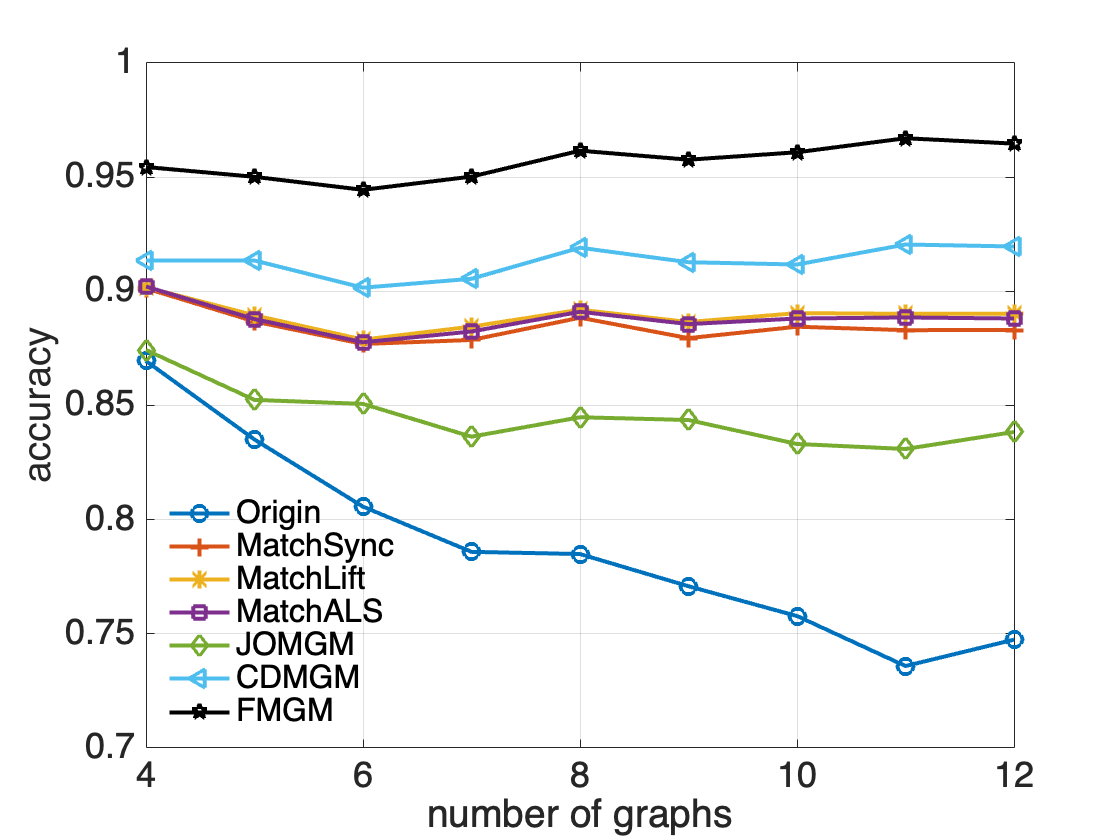

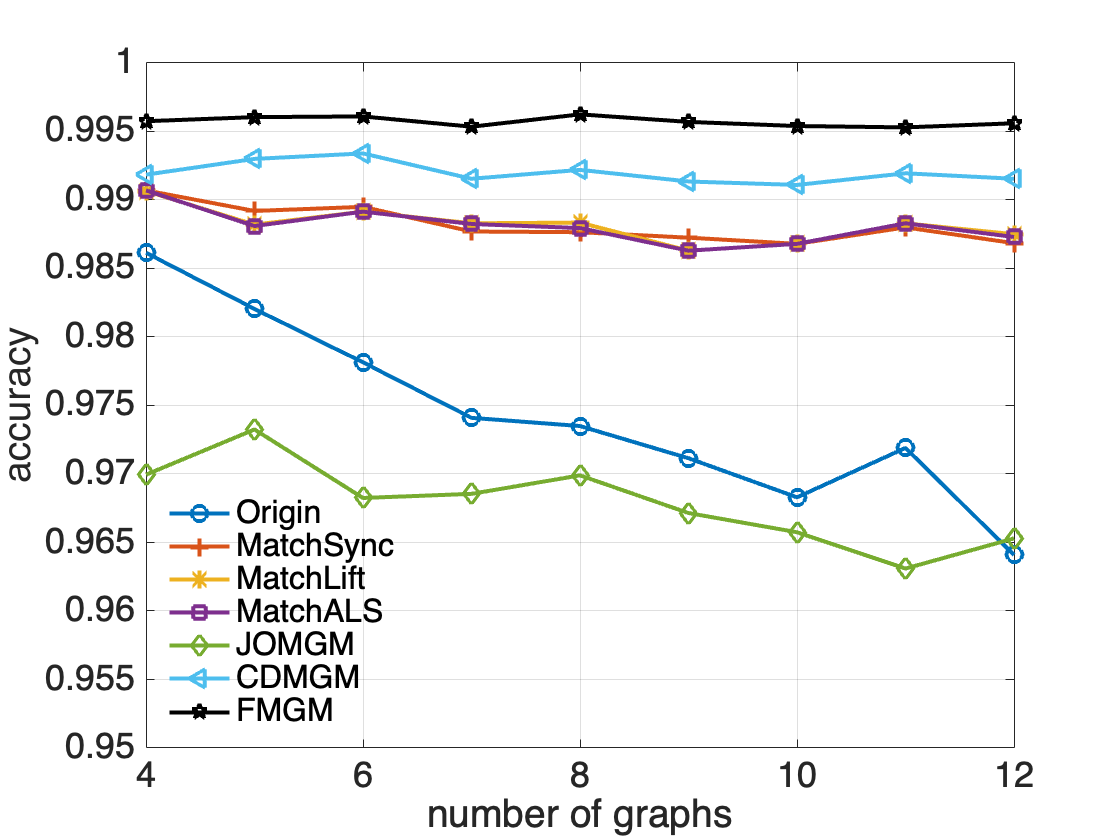

graph_num = 4:12;
for i = 1:length(files)
    fname = [files(i).folder, filesep, files(i).name];
    acc = importdata(fname);
    figure, hold on; 
    for k = 1:length(alglist)
        plot(graph_num, acc(:, k), ['-', mklist(k)], 'DisplayName', alglist{k}, 'Color', cmap(k, :));
    end
    hold off;
%     legend('Location', 'bestoutside');
    legend('Location', 'southwest');
    xlabel('number of graphs');
    ylabel('accuracy');
    if i == 2
        ylim([0.95, 1]);
    end
    exportgraphics(gcf, ['./imgs/', files(i).name(1:end-4), '.pdf']);
end

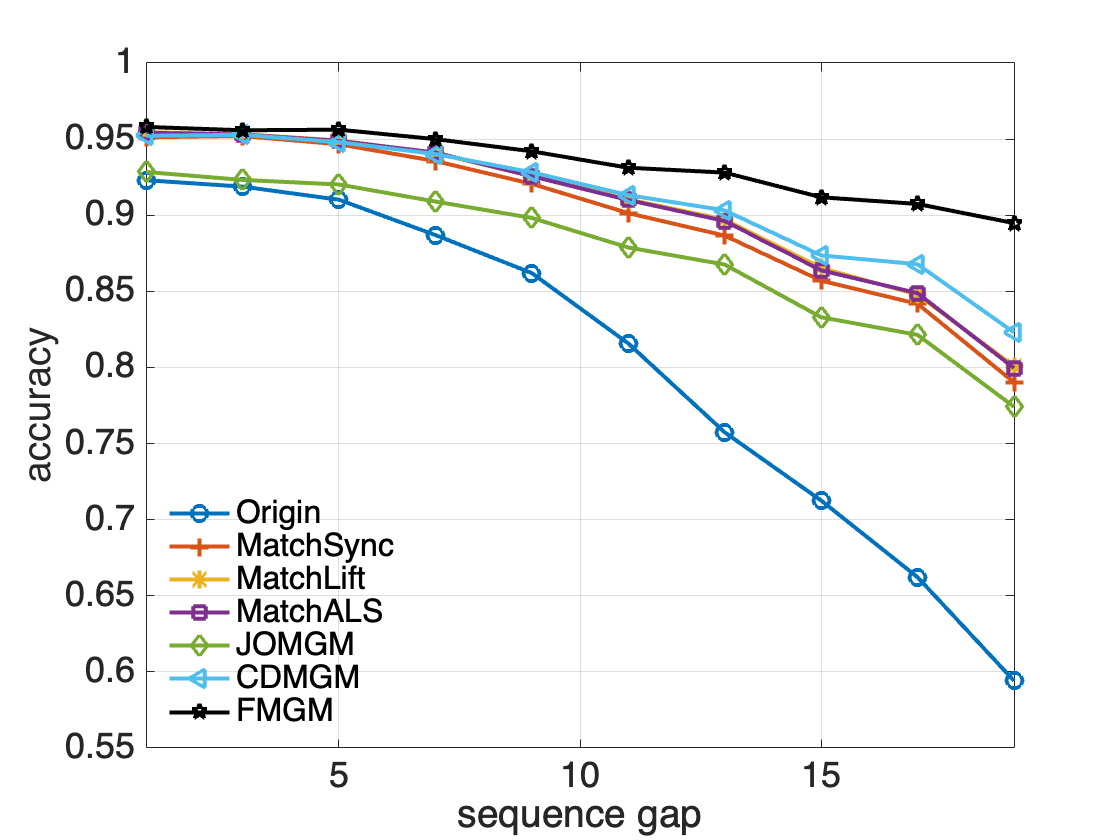

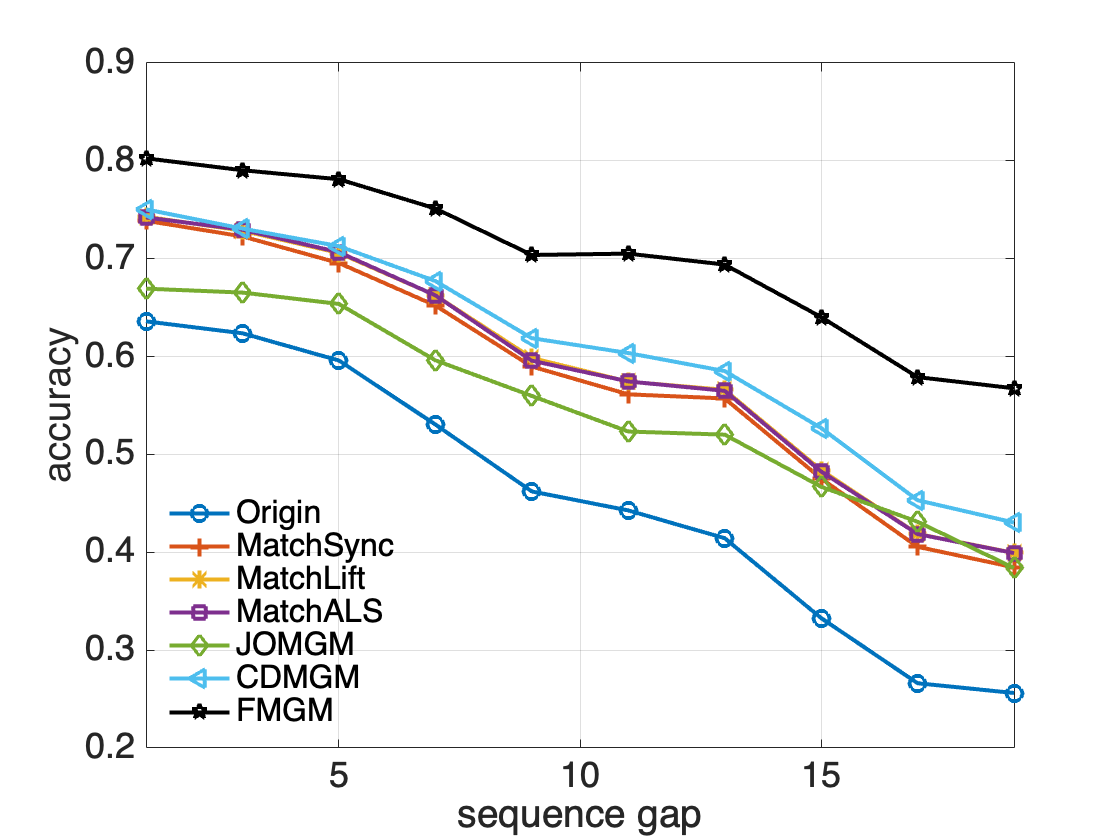

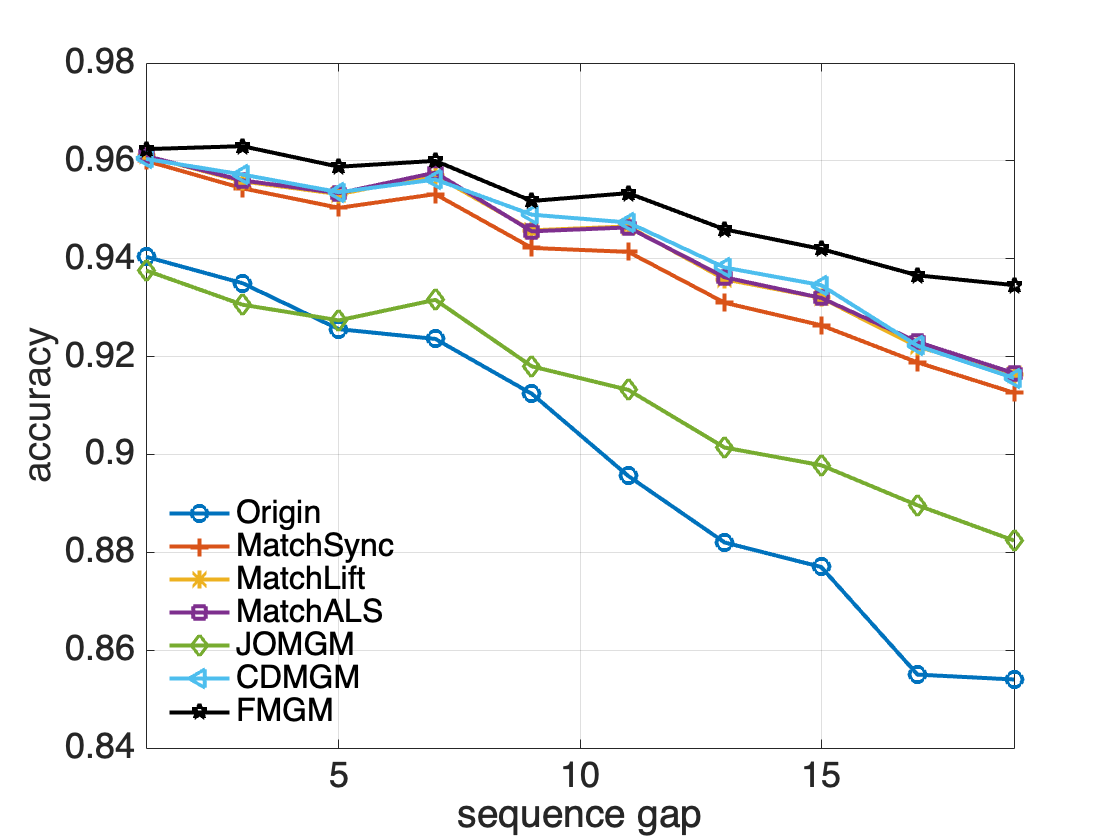

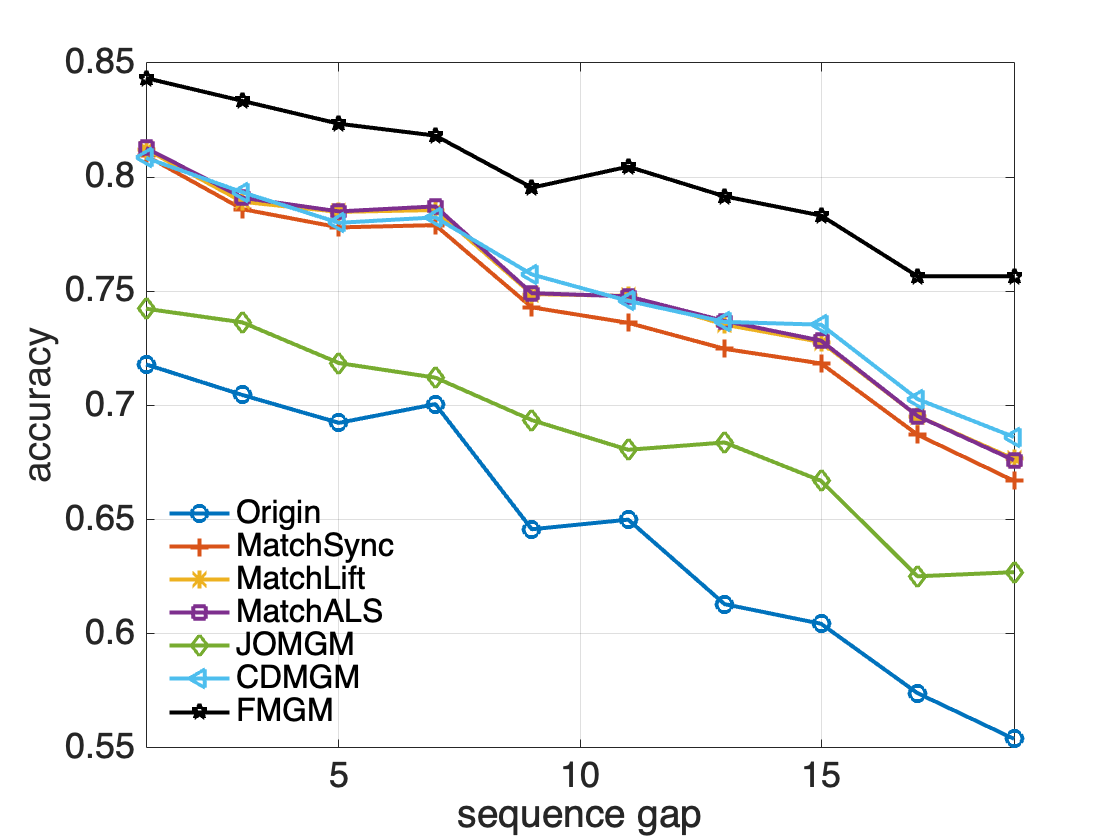

files = dir('./cmu_*_*.mat');
baseline = 1:2:20;
for i = 1:length(files)
    fname = [files(i).folder, filesep, files(i).name];
    acc = importdata(fname);
    figure, hold on; 
    for k = 1:length(alglist)
        plot(baseline, acc(:, k), ['-', mklist(k)], 'DisplayName', alglist{k}, 'Color', cmap(k, :));
    end
    hold off;
    legend('Location', 'southwest');
    xlabel('sequence gap');
    ylabel('accuracy');
    xlim([min(baseline), max(baseline)]);
    exportgraphics(gcf, ['./imgs/', files(i).name(1:end-4), '.pdf']);
end